syms theta1 theta2 a1 a2;
h1=[cos(theta1) -sin(theta1) 0 0 ; sin(theta1) cos(theta1) 0 0 ; 0 0 1 0;0 0 0 1];
h11=[1 0 0 a1 ; 0 1 0 0 ;0 0 1 0 ; 0 0 0 1];
T1=h1*h11;
h2=[cos(theta2) -sin(theta2) 0 0 ; sin(theta2) cos(theta2) 0 0 ; 0 0 1 0 ; 0 0 0 1];
h22=[1 0 0 a2;0 1 0 0 ; 0 0 1 0 ; 0 0 0 1 ];
T2=h2*h22;
H3=T1*T2;
disp(simplify(H3));

$$\left(\begin{array}{cccc} \cos\left(\theta_{1}+\theta_{2}\right) & -\sin\left(\theta_{1}+\theta_{2}\right) & 0 & a_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+a_{1}\,\cos\left(\theta_{1}\right)\\ \sin\left(\theta_{1}+\theta_{2}\right) & \cos\left(\theta_{1}+\theta_{2}\right) & 0 & a_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+a_{1}\,\sin\left(\theta_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

x = H3(1,4);
y = H3(2,4);
J = simplify(jacobian([x; y], [theta1 theta2]));
display(J);

$$J = \left(\begin{array}{cc} -a_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)-a_{1}\,\sin\left(\theta_{1}\right) & -a_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)\\ a_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+a_{1}\,\cos\left(\theta_{1}\right) & a_{2}\,\cos\left(\theta_{1}+\theta_{2}\right) \end{array}\right)$$

d = simplify(det(J))

$$d = a_{1}\,a_{2}\,\sin\left(\theta_{2}\right)$$

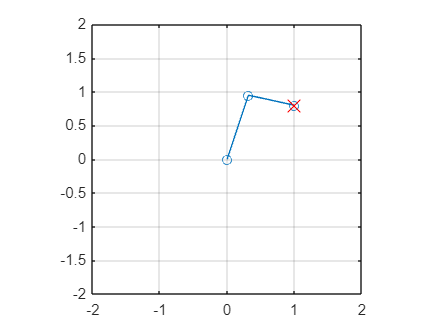


%يحل محل ال عمود المشترك لكن بارقام وليس رموزا 
l1 = 1; l2 = 0.7;
%يحل محل الزاوية الاولى والثانية بارقام ايضا
t1 = pi/4;
%تحليل المركبات لبدأ العمل 
x1=l1*cos(t1);
y1=l1*sin(t1);

% ---------- inverse kinematics ----------
px = input('Enter x: ');
py = input('Enter y: ');
r = sqrt(px^2 + py^2);
if r > l1 + l2 || r < abs(l1 - l2)
    error('Point is out of reach');
end
[v1,v2]=ik(px,py,l1,l2);
v1s=0;
v2s=0;
v1=linspace(v1s,v1,50);
v2=linspace(v2s,v2,50);


for i=1:50
    x1=l1*cos(v1(i));
    y1=l1*sin(v1(i));
    xc = l1*cos(v1(i)) + l2*cos(v1(i)+v2(i));
    yc = l1*sin(v1(i)) + l2*sin(v1(i)+v2(i));
    %cla عشان ميعملش خطوط كتير 
    cla;
    plot([0 x1 xc], [0 y1 yc], '-o');
    hold on ; 
    plot(px, py, 'rx', 'MarkerSize', 12);
    axis equal;
    axis([-2 2 -2 2]);
    grid on;
    drawnow;
end

display(rad2deg(v1));

         0    1.4608    2.9216    4.3824    5.8432    7.3040    8.7648   10.2256   11.6864   13.1472   14.6080   16.0688   17.5297   18.9905   20.4513   21.9121   23.3729   24.8337   26.2945   27.7553   29.2161   30.6769   32.1377   33.5985   35.0593   36.5201   37.9809   39.4417   40.9025   42.3633   43.8241   45.2849   46.7457   48.2065   49.6673   51.1282   52.5890   54.0498   55.5106   56.9714   58.4322   59.8930   61.3538   62.8146   64.2754   65.7362   67.1970   68.6578   70.1186   71.5794

